# Harmonic Oscillator

The system is defined by the following second-order differential equation,


$$\ddot{x} + \gamma \dot{x} + x = 0$$



$$\text{Now, let } y = \dot{x}
$$



$$\text{Then } \dot{y} = -x - \gamma y$$



$${(}\matrix{{\dot{x}} \cr {\dot{y}}})=(\matrix{0 & 1 \cr -1 & -\gamma})(\matrix{x\cr y})$$


## Parameters

Linear 2D system.

gamma_vals = 0.2:0.2:2.4;
A = [0 1; -1 0];   % matrix defined, where x'_vec = A.x_vec is the system.

Solve the equation using ODE45.

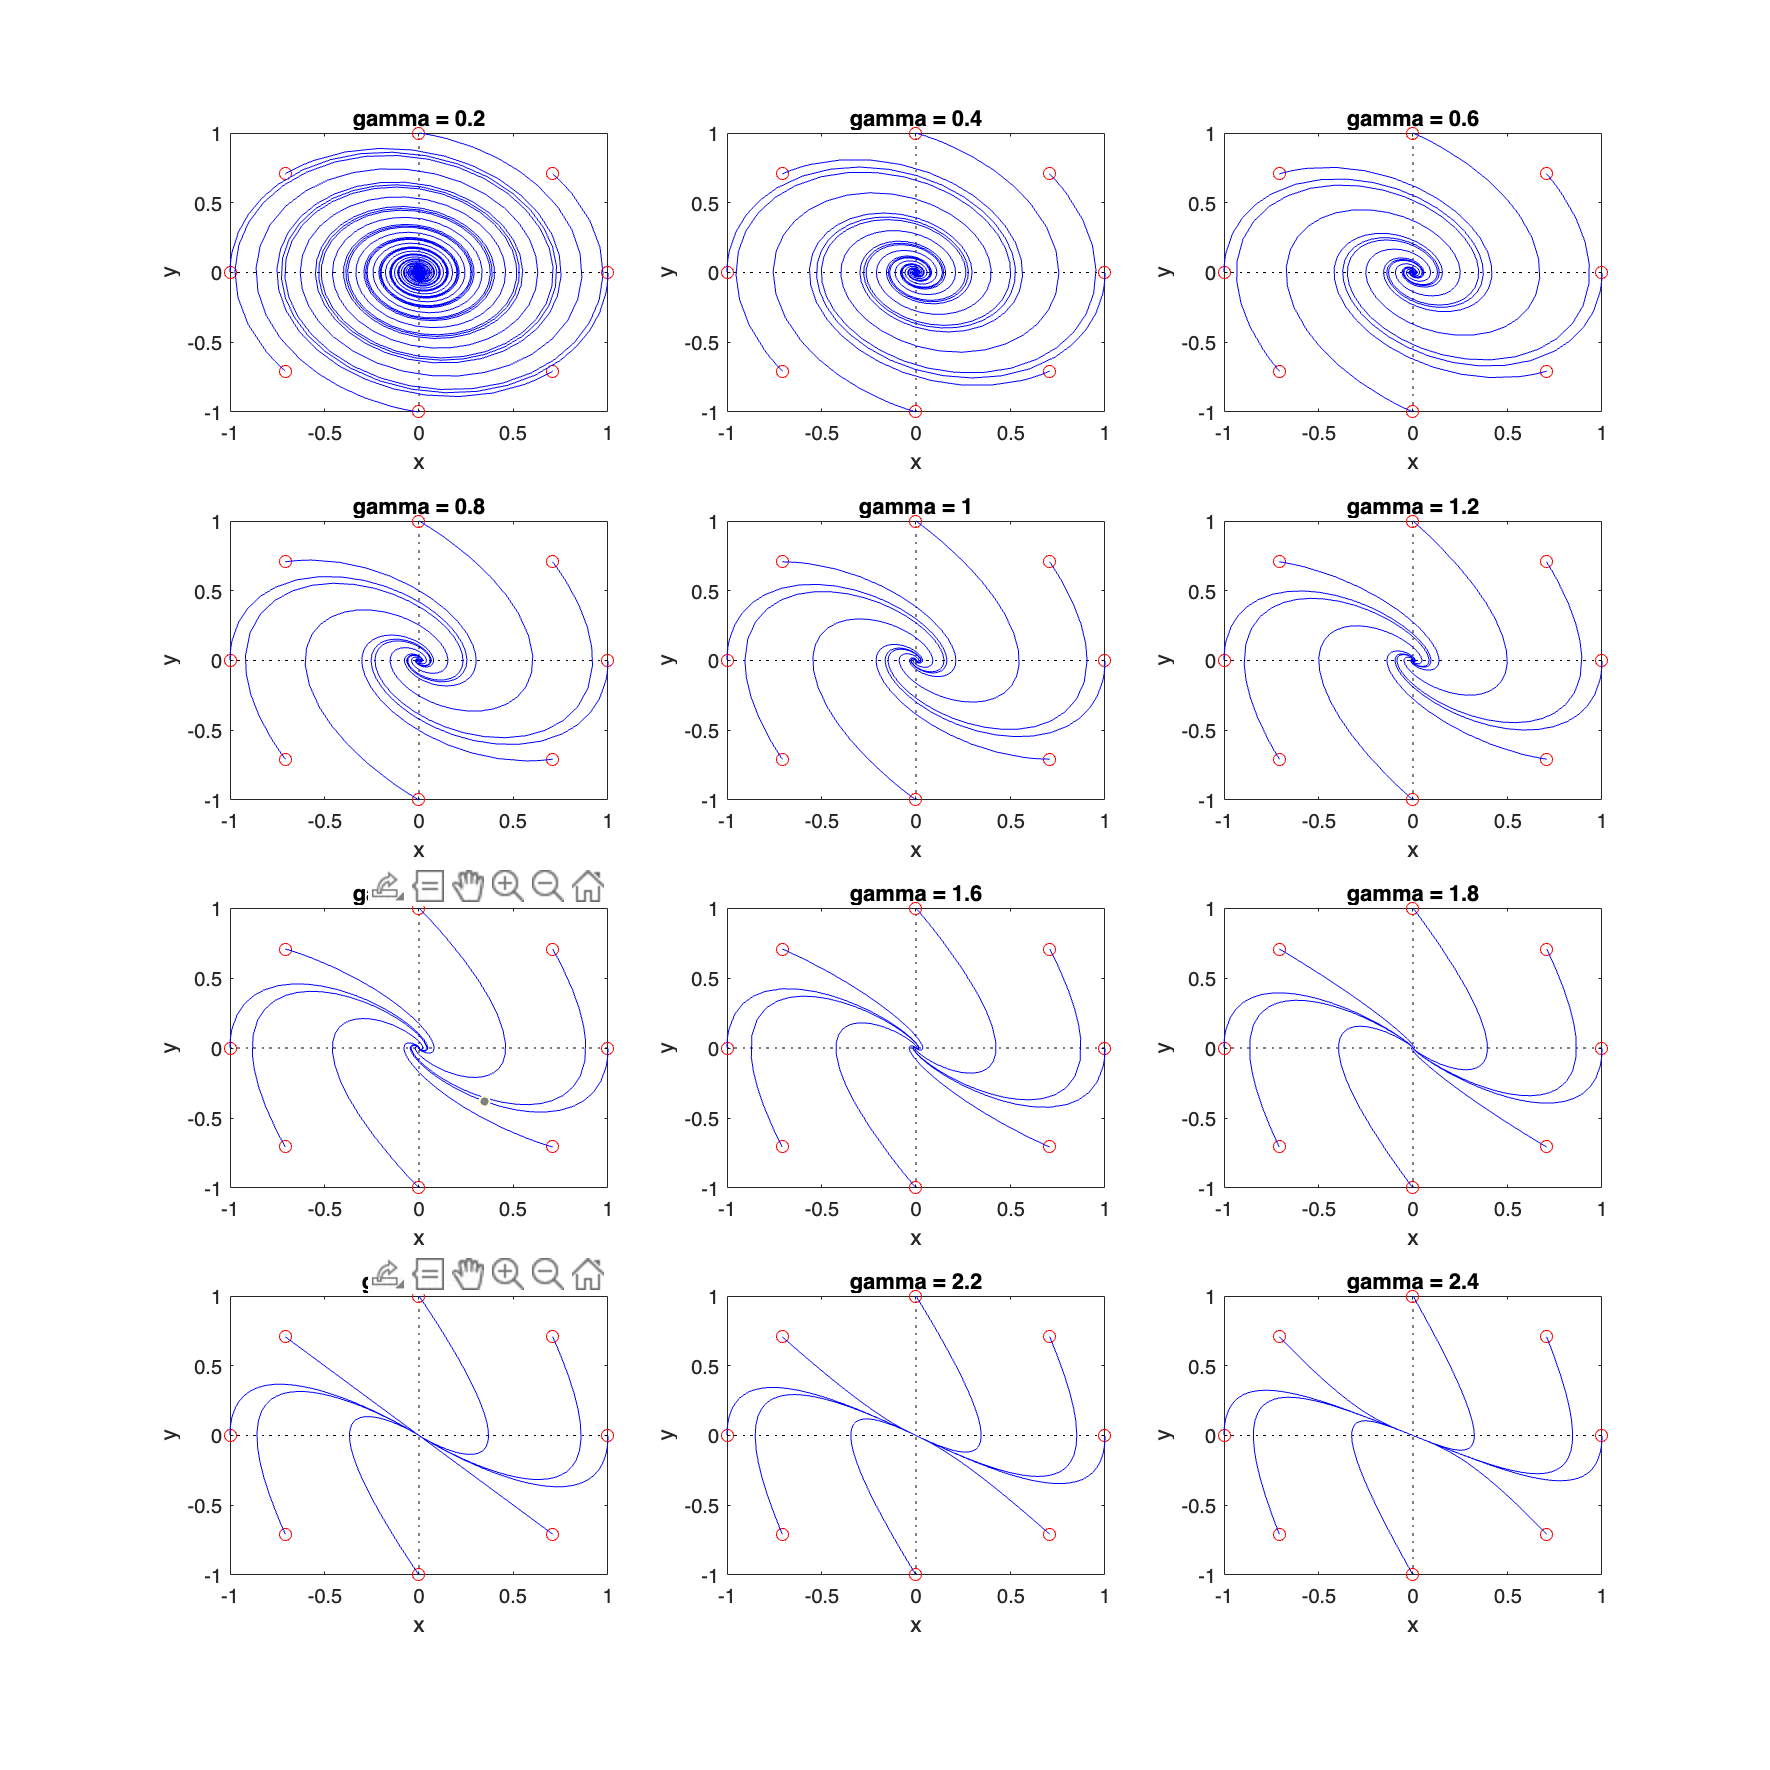

clf;
f = figure; hold on;
f.Position(3:4) = [3000 3000];

% iterate over values of gamma; set gamma in A each time.
for gamma_idx=1:length(gamma_vals)
    
    % define the equation.
    A(2,2) = -1 * gamma_vals(gamma_idx);
    dx = @(t, x)[A(1,1)*x(1) + A(1,2)*x(2); A(2,1)*x(1) + A(2,2)*x(2)];

    % set the starting points to be along the unit circle
    x_start = cos([0:2*pi/8:2*pi]);
    y_start = sin([0:2*pi/8:2*pi]);
    
    subplot(4, 3, gamma_idx);
    
    plot([-1 1],[0 0],'k:'); hold on;       %initial x axis (dotted)
    plot([0 0],[-1 1],'k:'); hold on;       %initial y axis (dotted)
    
    % axis square
    xlabel('x');
    ylabel('y');
    title(['gamma = ' num2str(-A(2,2))]);
    
    m1=0;   
    for ii=1:length(x_start)
        [tout, x] = ode45(dx, [0 100], [x_start(ii); y_start(ii)]);     % starting points on a circle
        plot(x_start(ii), y_start(ii), 'ro'); hold on;                  % plot the starting points in red
        plot(x(:,1), x(:,2), 'b-'); hold on;
    end  
end

**gamma = 2 is the critical value **for transition from underdamped to overdamped conditions.

For values lower than 2, the spring oscillates about the fixed point at (0, 0) and takes a long time to reach it by sprialling inwards.

For values higher than 2, the spring quickly approaches the fixed point; higher values of gamma dampen the spring even faster, i.e. without oscillating. 

## Now plot the vector field

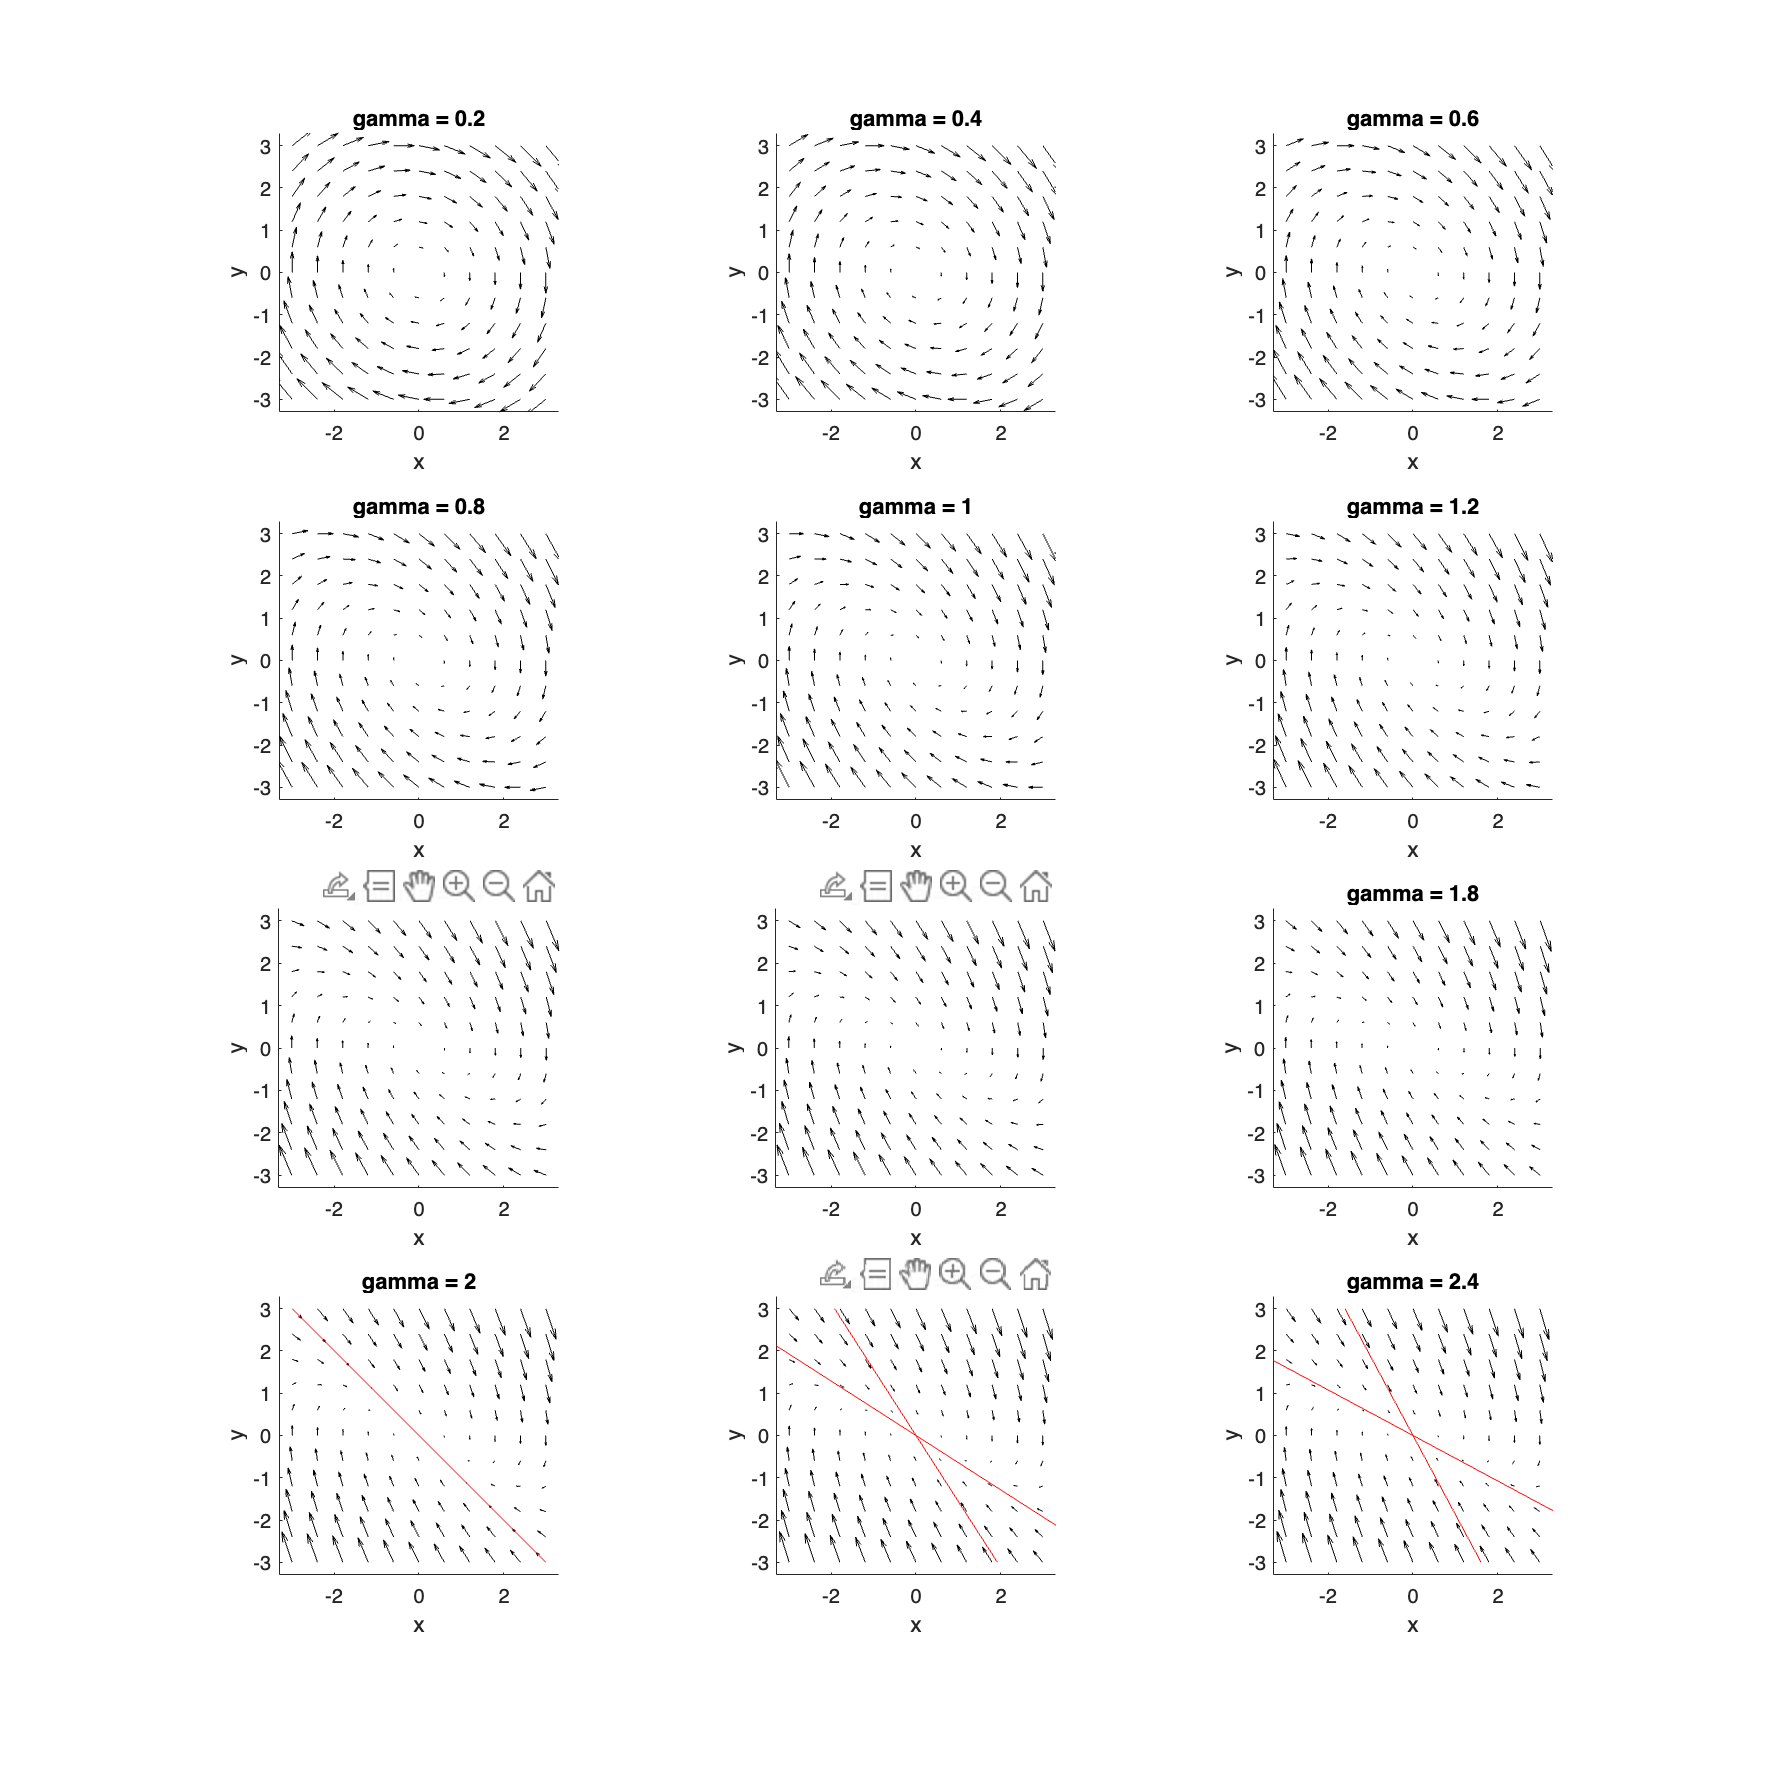

clf;
f = figure; hold on;
f.Position(3:4) = [3000 3000];

[y1,y2] = meshgrid([-3:0.6:3],[-3:0.6:3]);

% iterate over values of gamma; set gamma in A each time.
for gamma_idx=1:length(gamma_vals)
    
    % define the equation.
    A(2,2) = -1 * gamma_vals(gamma_idx);

    dy1dt = (A(1,1)*y1 + A(1,2)*y2);
    dy2dt = (A(2,1)*y1 + A(2,2)*y2);

    subplot(4, 3, gamma_idx);

    hold on;
    axis square
    quiver(y1, y2, dy1dt, dy2dt, 1, 'color', 'k');

    % plot eigenvectors.
    lamda1=0; lamda2=0;
    if det(A)<=(trace(A)^2)/4
        lamda1=(trace(A)+sqrt(trace(A)^2-4*det(A)))/2;
        lamda2=(trace(A)-sqrt(trace(A)^2-4*det(A)))/2;
        plot([-3*A(2,1)/(lamda1-A(2,2)) 3*A(2,1)/(lamda1-A(2,2))],[-3 3],'r-');
        plot([-3*A(2,1)/(lamda2-A(2,2)) 3*A(2,1)/(lamda2-A(2,2))],[-3 3],'r-');
    end

    xlabel('x');
    ylabel('y');
    title(['gamma = ' num2str(-A(2, 2))]);
    set(gca,'xlim',1.1*[-3 3],'ylim',1.1*[-3 3]);
end

## For gamma values less than 0.

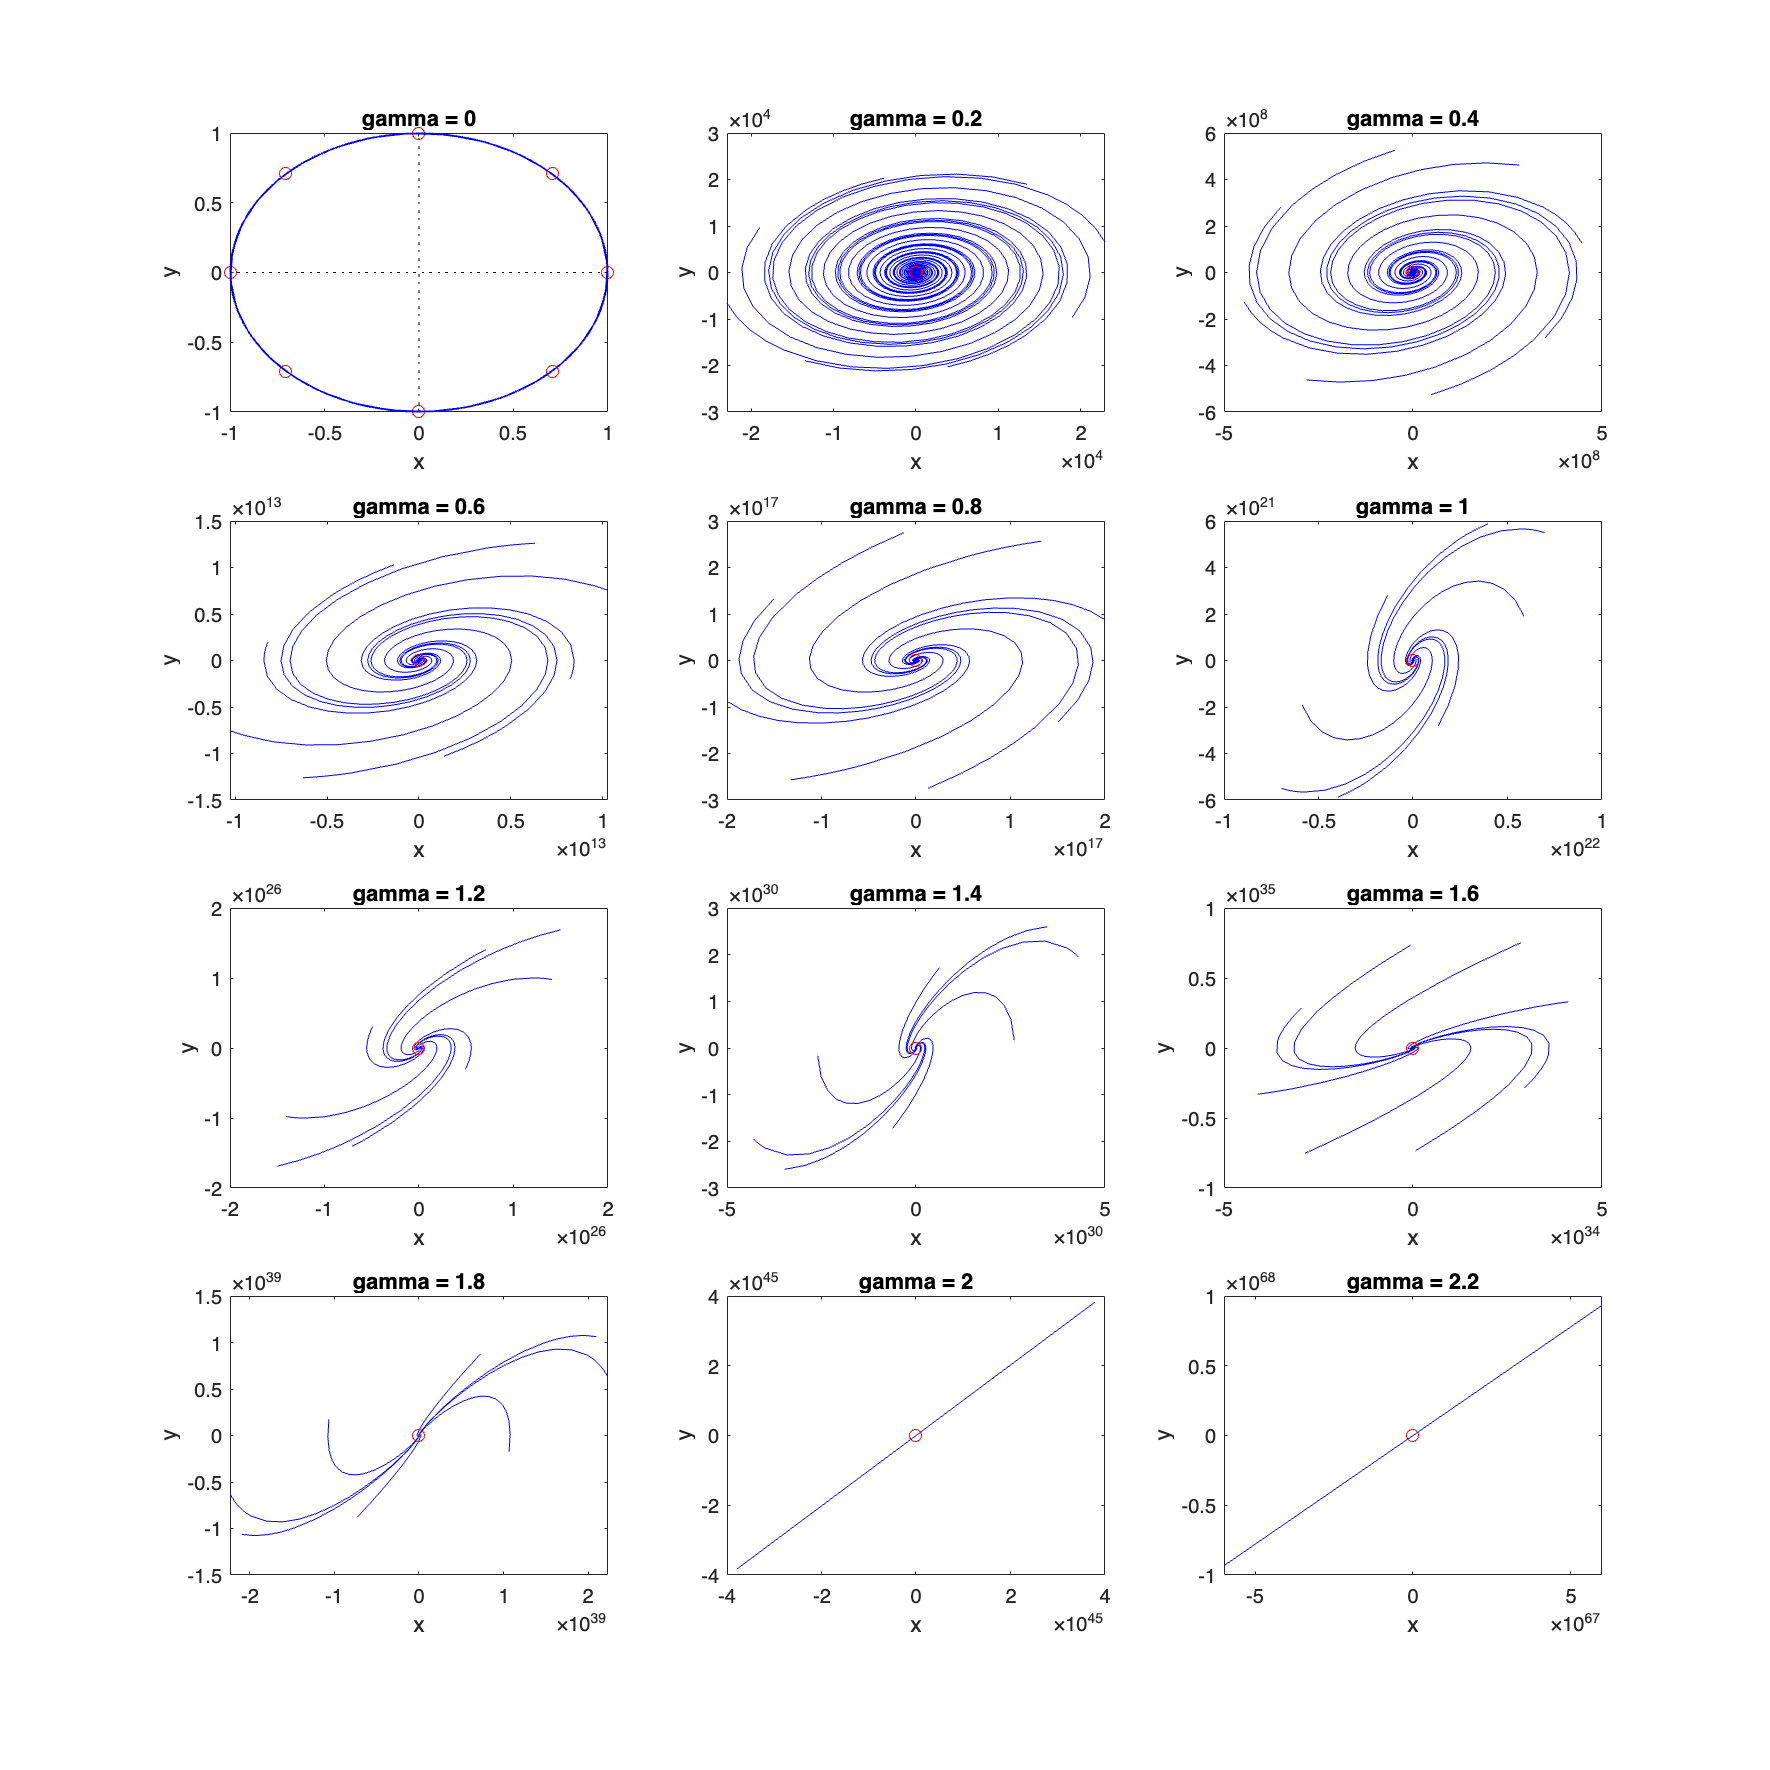

gamma_vals = 0:-0.2:-2.2;
clf;
f = figure; hold on;
f.Position(3:4) = [3000 3000];

% iterate over values of gamma; set gamma in A each time.
for gamma_idx=1:length(gamma_vals)
    
    % define the equation.
    A(2,2) = -1 * gamma_vals(gamma_idx);
    dx = @(t, x)[A(1,1)*x(1) + A(1,2)*x(2); A(2,1)*x(1) + A(2,2)*x(2)];

    % set the starting points to be along the unit circle
    x_start = cos([0:2*pi/8:2*pi]);
    y_start = sin([0:2*pi/8:2*pi]);
    
    subplot(4, 3, gamma_idx);
    
    plot([-1 1],[0 0],'k:'); hold on;       %initial x axis (dotted)
    plot([0 0],[-1 1],'k:'); hold on;       %initial y axis (dotted)
    
    % axis square
    xlabel('x');
    ylabel('y');
    title(['gamma = ' num2str(A(2,2))]);
    
    m1=0;   
    for ii=1:length(x_start)
        [tout, x] = ode45(dx, [0 100], [x_start(ii); y_start(ii)]);     % starting points on a circle
        plot(x_start(ii), y_start(ii), 'ro'); hold on;                  % plot the starting points in red
        plot(x(:,1), x(:,2), 'b-'); hold on;
    end  
end

For negative values of gamma, the "damping" force acts in the same direction as the velocity of the spring; consequently, it is not longer a "damping" force, but rather, causes the spring to move even faster. The amplitude of the oscillations keep increasing, causing the system to spiral out.

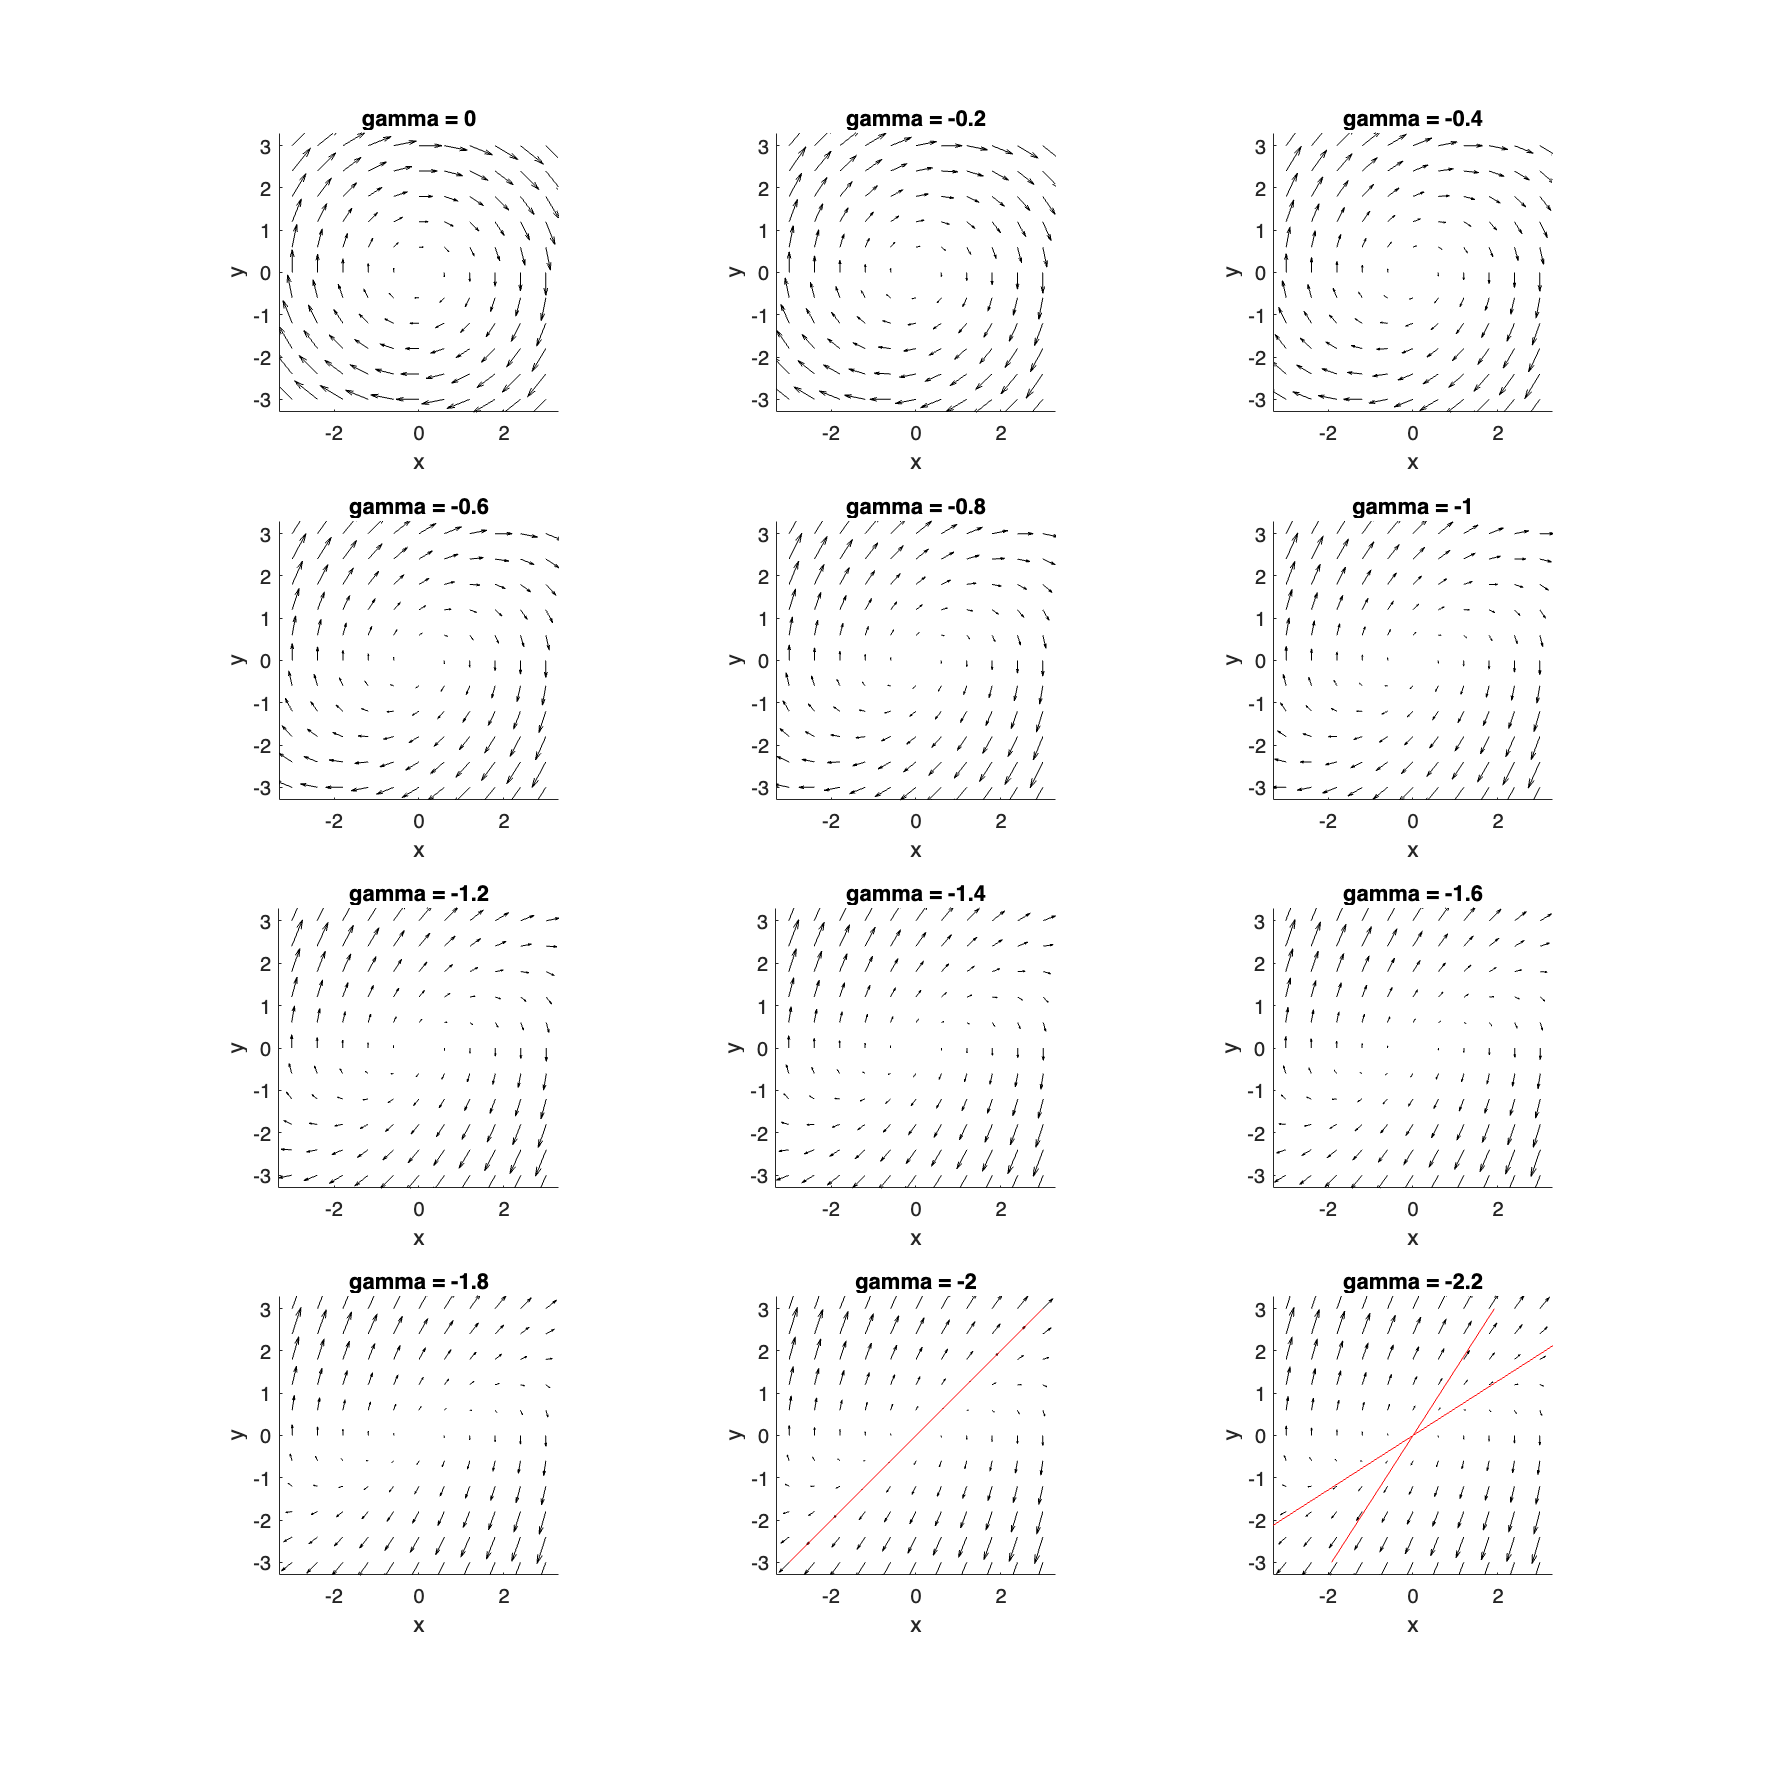

clf;
f = figure; hold on;
f.Position(3:4) = [3000 3000];

[y1,y2] = meshgrid([-3:0.6:3],[-3:0.6:3]);

% iterate over values of gamma; set gamma in A each time.
for gamma_idx=1:length(gamma_vals)
    
    % define the equation.
    A(2,2) = -1 * gamma_vals(gamma_idx);

    dy1dt = (A(1,1)*y1 + A(1,2)*y2);
    dy2dt = (A(2,1)*y1 + A(2,2)*y2);

    subplot(4, 3, gamma_idx);

    hold on;
    axis square
    quiver(y1, y2, dy1dt, dy2dt, 1, 'color', 'k');

    % plot eigenvectors.
    lamda1=0; lamda2=0;
    if det(A)<=(trace(A)^2)/4
        lamda1=(trace(A)+sqrt(trace(A)^2-4*det(A)))/2;
        lamda2=(trace(A)-sqrt(trace(A)^2-4*det(A)))/2;
        plot([-3*A(2,1)/(lamda1-A(2,2)) 3*A(2,1)/(lamda1-A(2,2))],[-3 3],'r-');
        plot([-3*A(2,1)/(lamda2-A(2,2)) 3*A(2,1)/(lamda2-A(2,2))],[-3 3],'r-');
    end

    xlabel('x');
    ylabel('y');
    title(['gamma = ' num2str(-A(2, 2))]);
    set(gca,'xlim',1.1*[-3 3],'ylim',1.1*[-3 3]);
end